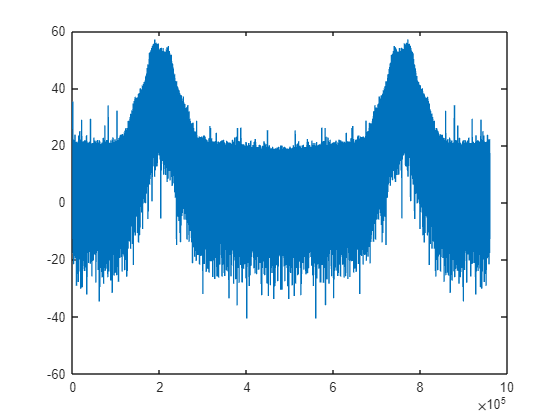

clear; 
close all; 
load("Radio_signal.mat")

x = raw_radio_94_2MHz;
Fs = 960000;
Fc = 200000;
Fcd = 57000;
t = 0:(1/Fs):10;
plot(20*log10(abs(fft(x, Fs))))

x = x(1:length(t));
cs = cos(2*pi*Fc*t);
xc = x'.*cs;
f1 = fir1(101, 0.1);

xl = filter(f1, 1, xc);

si = -sin(2*pi*Fc*t);
xs = x'.*si;
xls = filter(f1, 1, xs);
xlsj = xls * 1j;

xn = xlsj + xl;

xz = circshift(xn, -1);
xzs = conj(xz);
y = xn.*xzs;
yn = angle(y);

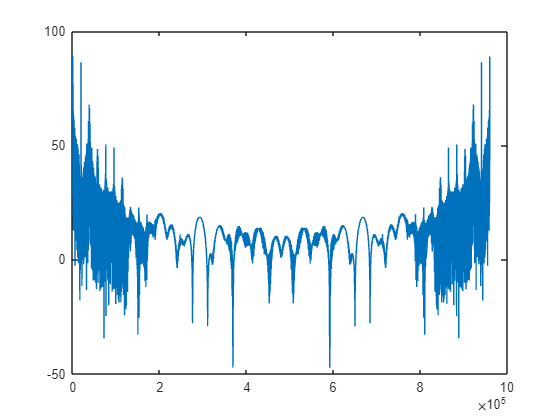

ys = downsample(yn, 5);
sound(ys, 192000)

csh = cos(2*pi*Fcd*t);
xd = yn .* csh;
plot(20*log10(abs(fft(yn, Fs))));

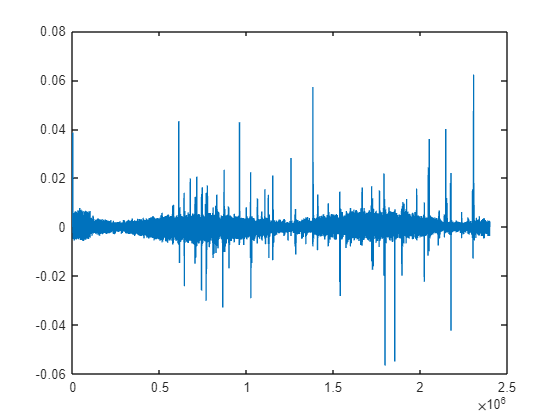

yds = downsample(xd, 4);
f2 = fir1(101, 0.02);
xdl = filter(f2, 1, yds);
t2 = 0:(1/240000):10;
plot(xdl);

xdl = xdl-mean(xdl);
xdl = xdl./rms(xdl);
bitrate = 1187.5;

ci = cos(2*pi*4750*t2);

[~, b] = findpeaks(ci);
xdk = xdl(b);
xdk = xdk(2:end);

xdk(3:4:end) = -xdk(3:4:end);
xdk(4:4:end) = -xdk(4:4:end);

k = 1;
for i=4:4:length(xdk)
    xds(k) = sum(xdk((i-3):i));
    k = k+1;
end

for i=1:1:length(xds)
    if xds(i) >= 0
        xds(i) = 1;
    else
        xds(i) = 0;
    end
end

dec = comm.DifferentialDecoder();

xbit = dec(xds');

a = 1;
b = 26;

while 1
    vec = xbit(a:b);
    message = vec(1:16);
    cw = vec(17:26);
    shi = [0;0;0;0;0;0;0;0;0;0];
    mx = cat(1,message,shi);
    mv = flip(mx');
    gx = [1 0 1 1 0 1 1 1 0 0 1];
    gx = flip(gx);
    [~,r] = gfdeconv(mv ,gx);
    r = flip(r);
    if length(r) < 10
        switch length(r)
            case 9
                r = cat(2, 0, r);
            case 8
                r = cat(2,[0 0], r);
            case 7
                r = cat(2,[0 0 0], r);
            case 6
                r = cat(2,[0 0 0 0], r);
            case 5
                r = cat(2,[0 0 0 0 0], r);
            case 4
                r = cat(2,[0 0 0 0 0 0], r);
            case 3
                r = cat(2,[0 0 0 0 0 0 0], r);
            case 2
                r = cat(2,[0 0 0 0 0 0 0 0 0], r);
            case 1
                r = cat(2,[0 0 0 0 0 0 0 0 0 0], r);
            otherwise
                r = [0 0 0 0 0 0 0 0 0 0];
        end
    end
    check = xor(cw', [0 0 1 1 1 1 1 1 0 0]);
    if check == r
        break
    end
    a = a+1;
    b = b+1;
end
a

a = 65

b

b = 90